# Example 9.2: Compute the CEP

Nicholas O'Donoughue 1 July 2019

*For the same covariance matrix defined above in Example 9.1, compute the *$$\mathrm{CEP}_{50}$$*.*

## Solution

% Set up error covariance matrix
C = [10, -3;
     -3, 5];


Just as in Example 9.1, we start by computing the eigenvalues, which are then given as $$\lambda_{\mathrm{max}}=11.4051$$ and $$\lambda_{\mathrm{min}}=3.4959$$. To compute CEP, we next take the square root of the ratio:


$$	\sqrt{\frac{\lambda_{\mathrm{min}}}{\lambda_{\mathrm{max}}}}=\frac{1.8960}{3.3771}=0.56$$


[V,D] = eig(C);
[lam_sort,i_sort] = sort(diag(D),'descend');
v_max = V(:,i_sort(1));
v_min = V(:,i_sort(2));

eig_ratio = sqrt(lam_sort(2)/lam_sort(1));

if eig_ratio > .5
    cep50 = .59*(sqrt(lam_sort(1)) + sqrt(lam_sort(2)));
else
    cep50 = sqrt(lam_sort(1))*(.67+.8*lam_sort(2)/lam_sort(1));
end
fprintf('CEP50 (calculated manually): %.2f \n',cep50);

CEP50 (calculated manually): 3.11 


Alternatively, we can simply supply the covariance matrix to the provided function `computeCEP50`.

% Compute the CEP 50
cep50 = utils.computeCEP50(C);
fprintf('CEP50 (calculated automatically): %.2f \n',cep50);

CEP50 (calculated automatically): 3.11 


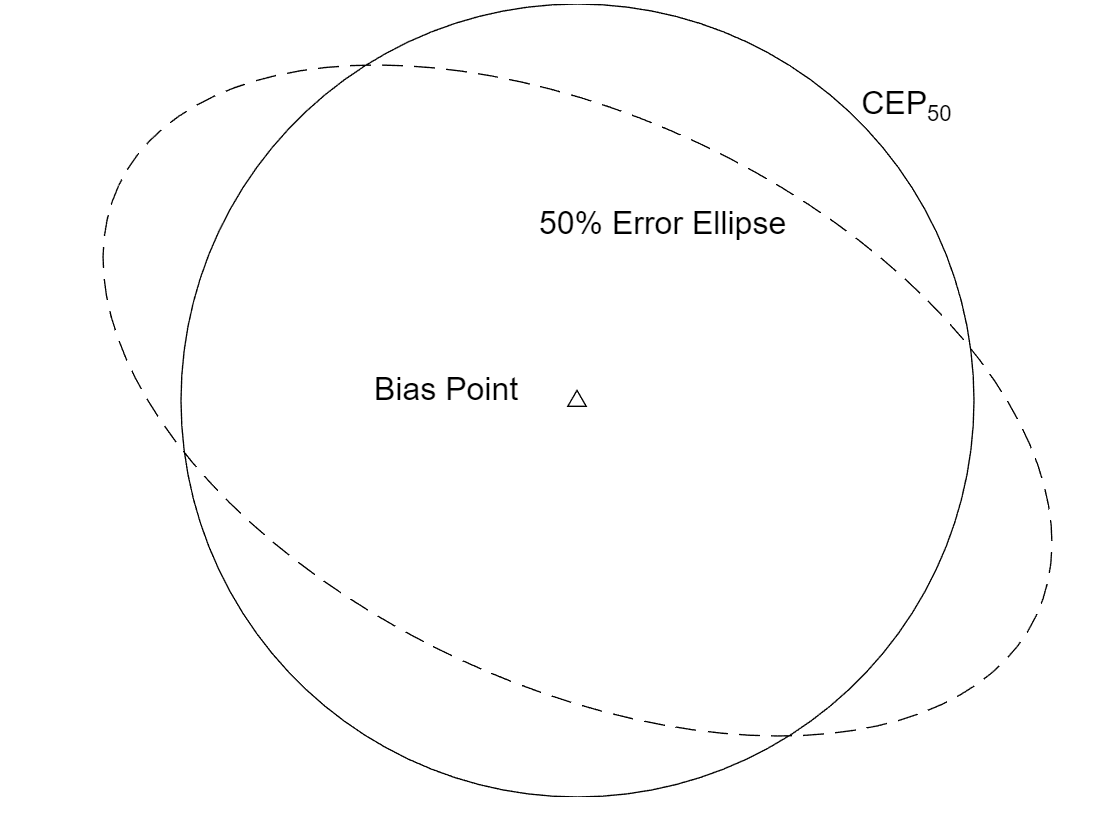


ell = utils.drawErrorEllipse([0,0]',C,101,50);
ell_cep = utils.drawCEP50([0,0]',C,101);

fig=figure;
plot(0,0,'k^','DisplayName','Bias Point');hold on;
plot(ell(1,:),ell(2,:),'k--','DisplayName','Error Ellipse');
plot(ell_cep(1,:),ell_cep(2,:),'k-','DisplayName','$CEP_{50}$');
text(-1.6,.1,'Bias Point','FontSize',12);
text(-.3,1.4,'50% Error Ellipse','FontSize',12);
text(2.2,2.3,'CEP_{50}','FontSize',12);

%xlabel('x');
%ylabel('y');
%legend('Location','NorthWest');
utils.setPlotStyle(gca,{'equal','clean','tight'});